# Chapter 8 Graphical Representation

## Plots of Univariant Series

T = readtable("grafuniv.xlsx",ReadRowNames=true);


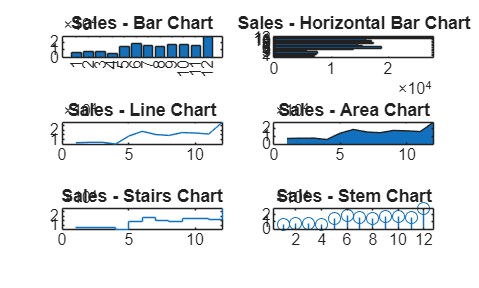

% PLOT THE sales using vertical bars , horizontal bars, line, area , stairs
% and stem charts.
% Plot sales data using different chart types
figure;
subplot(3, 2, 1);
bar(T.Sales);
title('Sales - Bar Chart');


subplot(3, 2, 2);
hBar = barh(T.Sales);
title('Sales - Horizontal Bar Chart');

subplot(3, 2, 3);
plot(T.Sales);
title('Sales - Line Chart');

subplot(3, 2, 4);
area(T.Sales);
title('Sales - Area Chart');

subplot(3, 2, 5);
stairs(T.Sales);
title('Sales - Stairs Chart');

subplot(3, 2, 6);
stem(T.Sales);
title('Sales - Stem Chart');

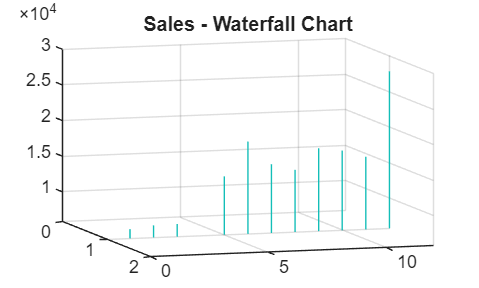

% waterfall chart
%subplot(3, 2, 7);
figure
waterfall(T.Sales);
title('Sales - Waterfall Chart');

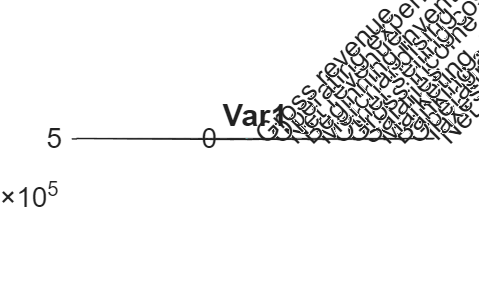

ans =   3×1 graphics array:

  GraphicsPlaceholder
  Patch
  Patch


waterfallchart(T)

T = readtable("Waterfall.xlsx",Sheet="Balance",ReadRowNames=true,Range="A1:B14")

T = 13×1 table
                                           Var1   
                                        __________

    Gross revenue                       2.4563e+05
    Operating expenses                       -2412
    Net revenue                         2.4322e+05
    Beginning inventory                 -1.149e+05
    Merchandising                           -18731
    Other selling costs                      -6244
    Gross income                        1.0334e+05
    Salaries                                -26745
    Marketing, advertising …                -11279
    Banking and insurance expenses …        -36000
    Operating income                         29321
    Taxes                                    -4400
    Net income          

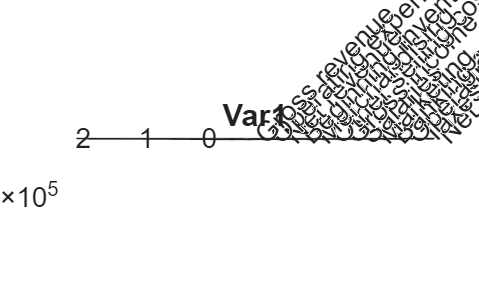

waterfallchart(T,'SetAsTotal',[1 3 7 11 13]);

title('Sales - Waterfall Chart with Totals');
% Create a new figure for the waterfall chart
figure;
waterfallchart(T, 'SetAsTotal', [1 3 7 11 13]);
title('Sales - Waterfall Chart with Totals');

YY = readtable("grafuniv2serie.xlsx",Sheet="data",ReadRowNames=true);

%